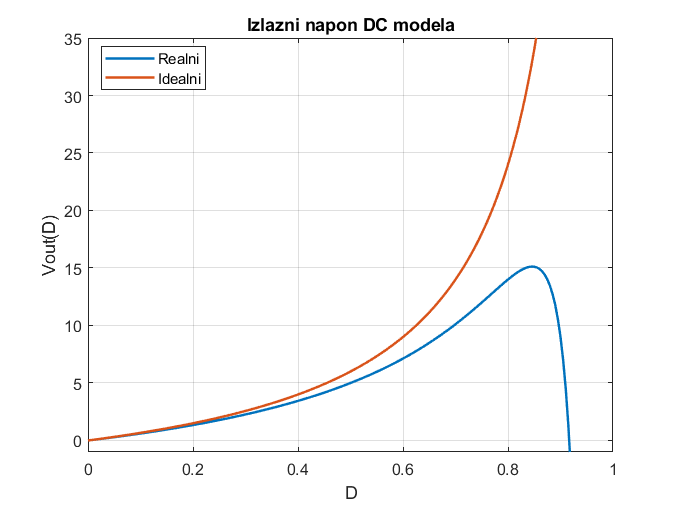

close all
clear
L=10e-6;
C=1000e-6;
rl=0.1;
rc=0.1;
A1=[-rl/L, 0,  0,  0;0, 0,  -1/L,0;0, 1/C, 0,  0;0, 0,  0,  0];
B1=[1/L,0;0, 0;0, 0;0, -1/C];
C1=[0, 0,  0,  1];
D1=[0, -rc];
A2=[-(rl+rc)/L, rc/L,-1/L,-1/L;rc/L,  -rc/L,  0,  1/L;1/C,0,  0,  0;1/C,-1/C,0,  0];
B2=[1/L,rc/L;0, -rc/L;0, 0;0, -1/C] ;
C2=[rc, -rc, 0,  1];
D2=[0, -rc];
%DC operating point
% Minimalni napon
Vin=6;
Iout=5;
%Po D0
D0=0:0.005:0.999;
U0=[Vin;Iout];
Vout=zeros(1,length(D0));
for i=1:length(D0)
%Averaged matrix
A=A1*D0(i)+A2*(1-D0(i));
B=B1*D0(i)+B2*(1-D0(i));
C=C1*D0(i)+C2*(1-D0(i));
D=D1*D0(i)+D2*(1-D0(i));
%DC model
X0=-inv(A)*B*U0;
Y0=(D-C/A*B)*U0;
Vout(i)=Y0(1,1);
end
plot(D0,Vout,'LineWidth',1.5)
hold on
plot(D0,D0./(1-D0)*Vin,'LineWidth',1.5)
grid on
ylim([-1 35])
title('Izlazni napon DC modela')
xlabel('D')
ylabel('Vout(D)')
legend('Realni','Idealni','Location',"best")
hold off

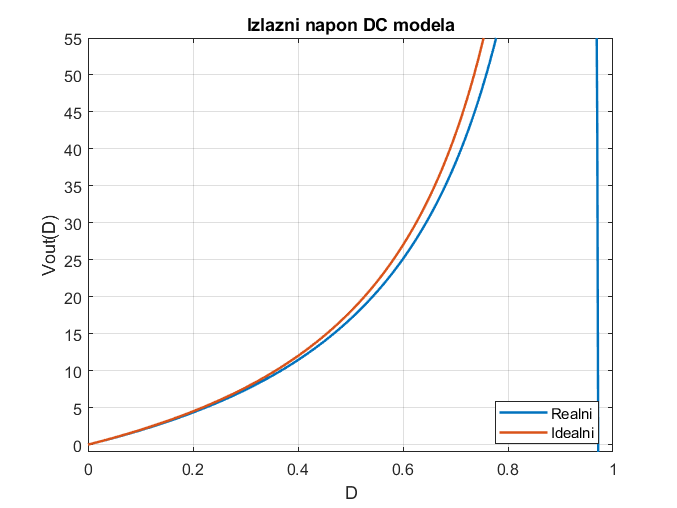



% Maximalni napon
Vin=18;
Iout=5;
%Po D0
D0=0:0.005:0.999;
U0=[Vin;Iout];
Vout=zeros(1,length(D0));
for i=1:length(D0)
%Averaged matrix
A=A1*D0(i)+A2*(1-D0(i));
B=B1*D0(i)+B2*(1-D0(i));
C=C1*D0(i)+C2*(1-D0(i));
D=D1*D0(i)+D2*(1-D0(i));
%DC model
X0=-inv(A)*B*U0;
Y0=(D-C/A*B)*U0;
Vout(i)=Y0(1,1);
end
plot(D0,Vout,'LineWidth',1.5)
hold on
plot(D0,D0./(1-D0)*Vin,'LineWidth',1.5)
grid on
ylim([-1 55])
title('Izlazni napon DC modela')
xlabel('D')
ylabel('Vout(D)')
legend('Realni','Idealni','Location',"best")
hold off